# **EVALUACIÓN 11.2. Planeación de Trayectorias**

**Jesús Alejandro Gómez Bautista | A01736171**

- **Obtener** el mapa de puntos para generar la planeación de trayectorias a partir de tu rostro, marcando **set-****points** con el software Geogebra.

- **Planear** la trayectoria que debe seguir el algoritmo empleando el mapa de puntos obtenido, considerando la descripción más próxima a los rasgos físicos de tu rostro (Forma de la cara, forma del cabello, ojos, cejas, nariz, boca y orejas), (barba en caso de que aplique).

- **Implementar** el código requerido para generar la planeación de trayectorias empleado la técnica que consideres más eficiente para esta aplicación (**Control en lazo abierto, control de posición, control de trayectorias** **ó** **PurePursuit** **(****way-points****)**). Considerando el ajuste de los parámetros cinemáticos del robot móvil como: Velocidad angular (w), velocidad lineal (v), ancho de la muestra (ts), tiempo de simulación (t), ganacias, etc.

**Foto base empleada para la extracción de puntos**

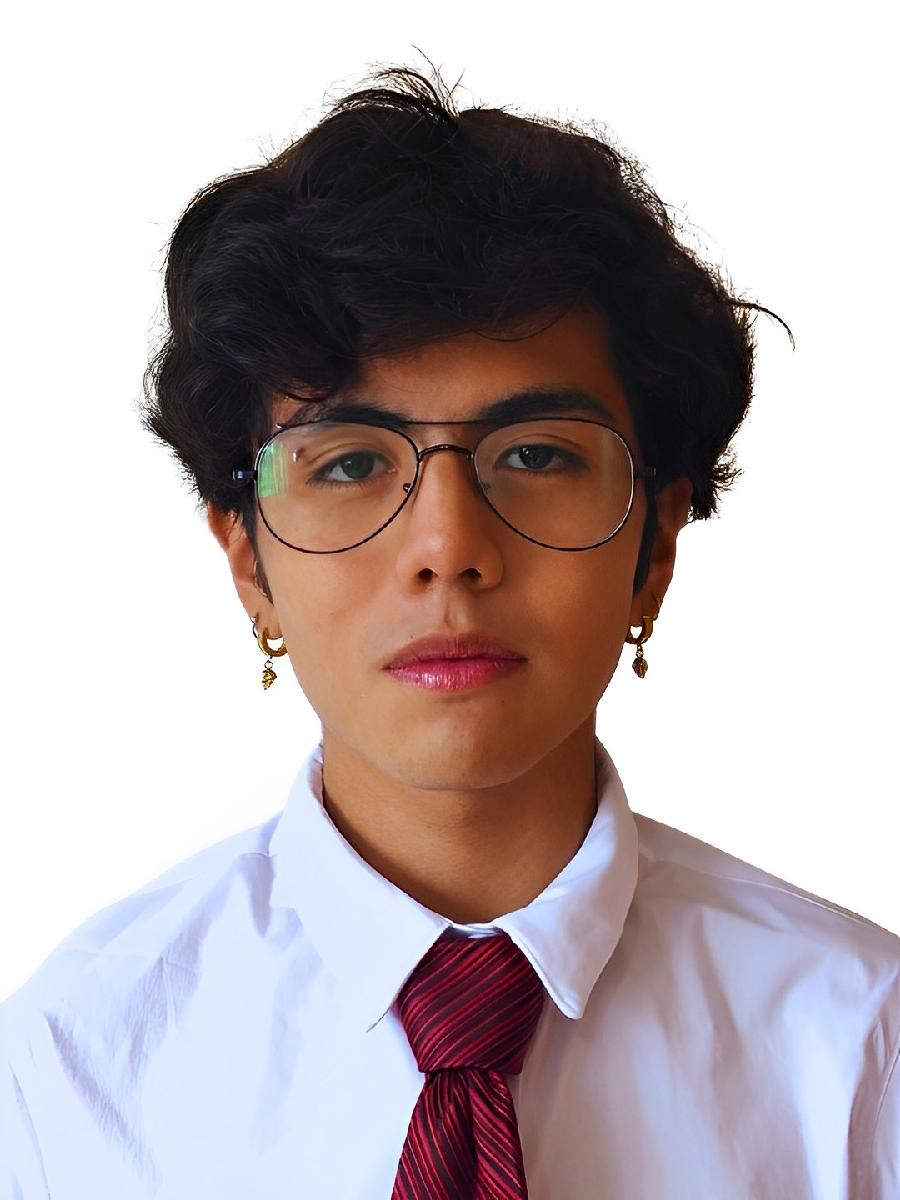

**Puntos generados**

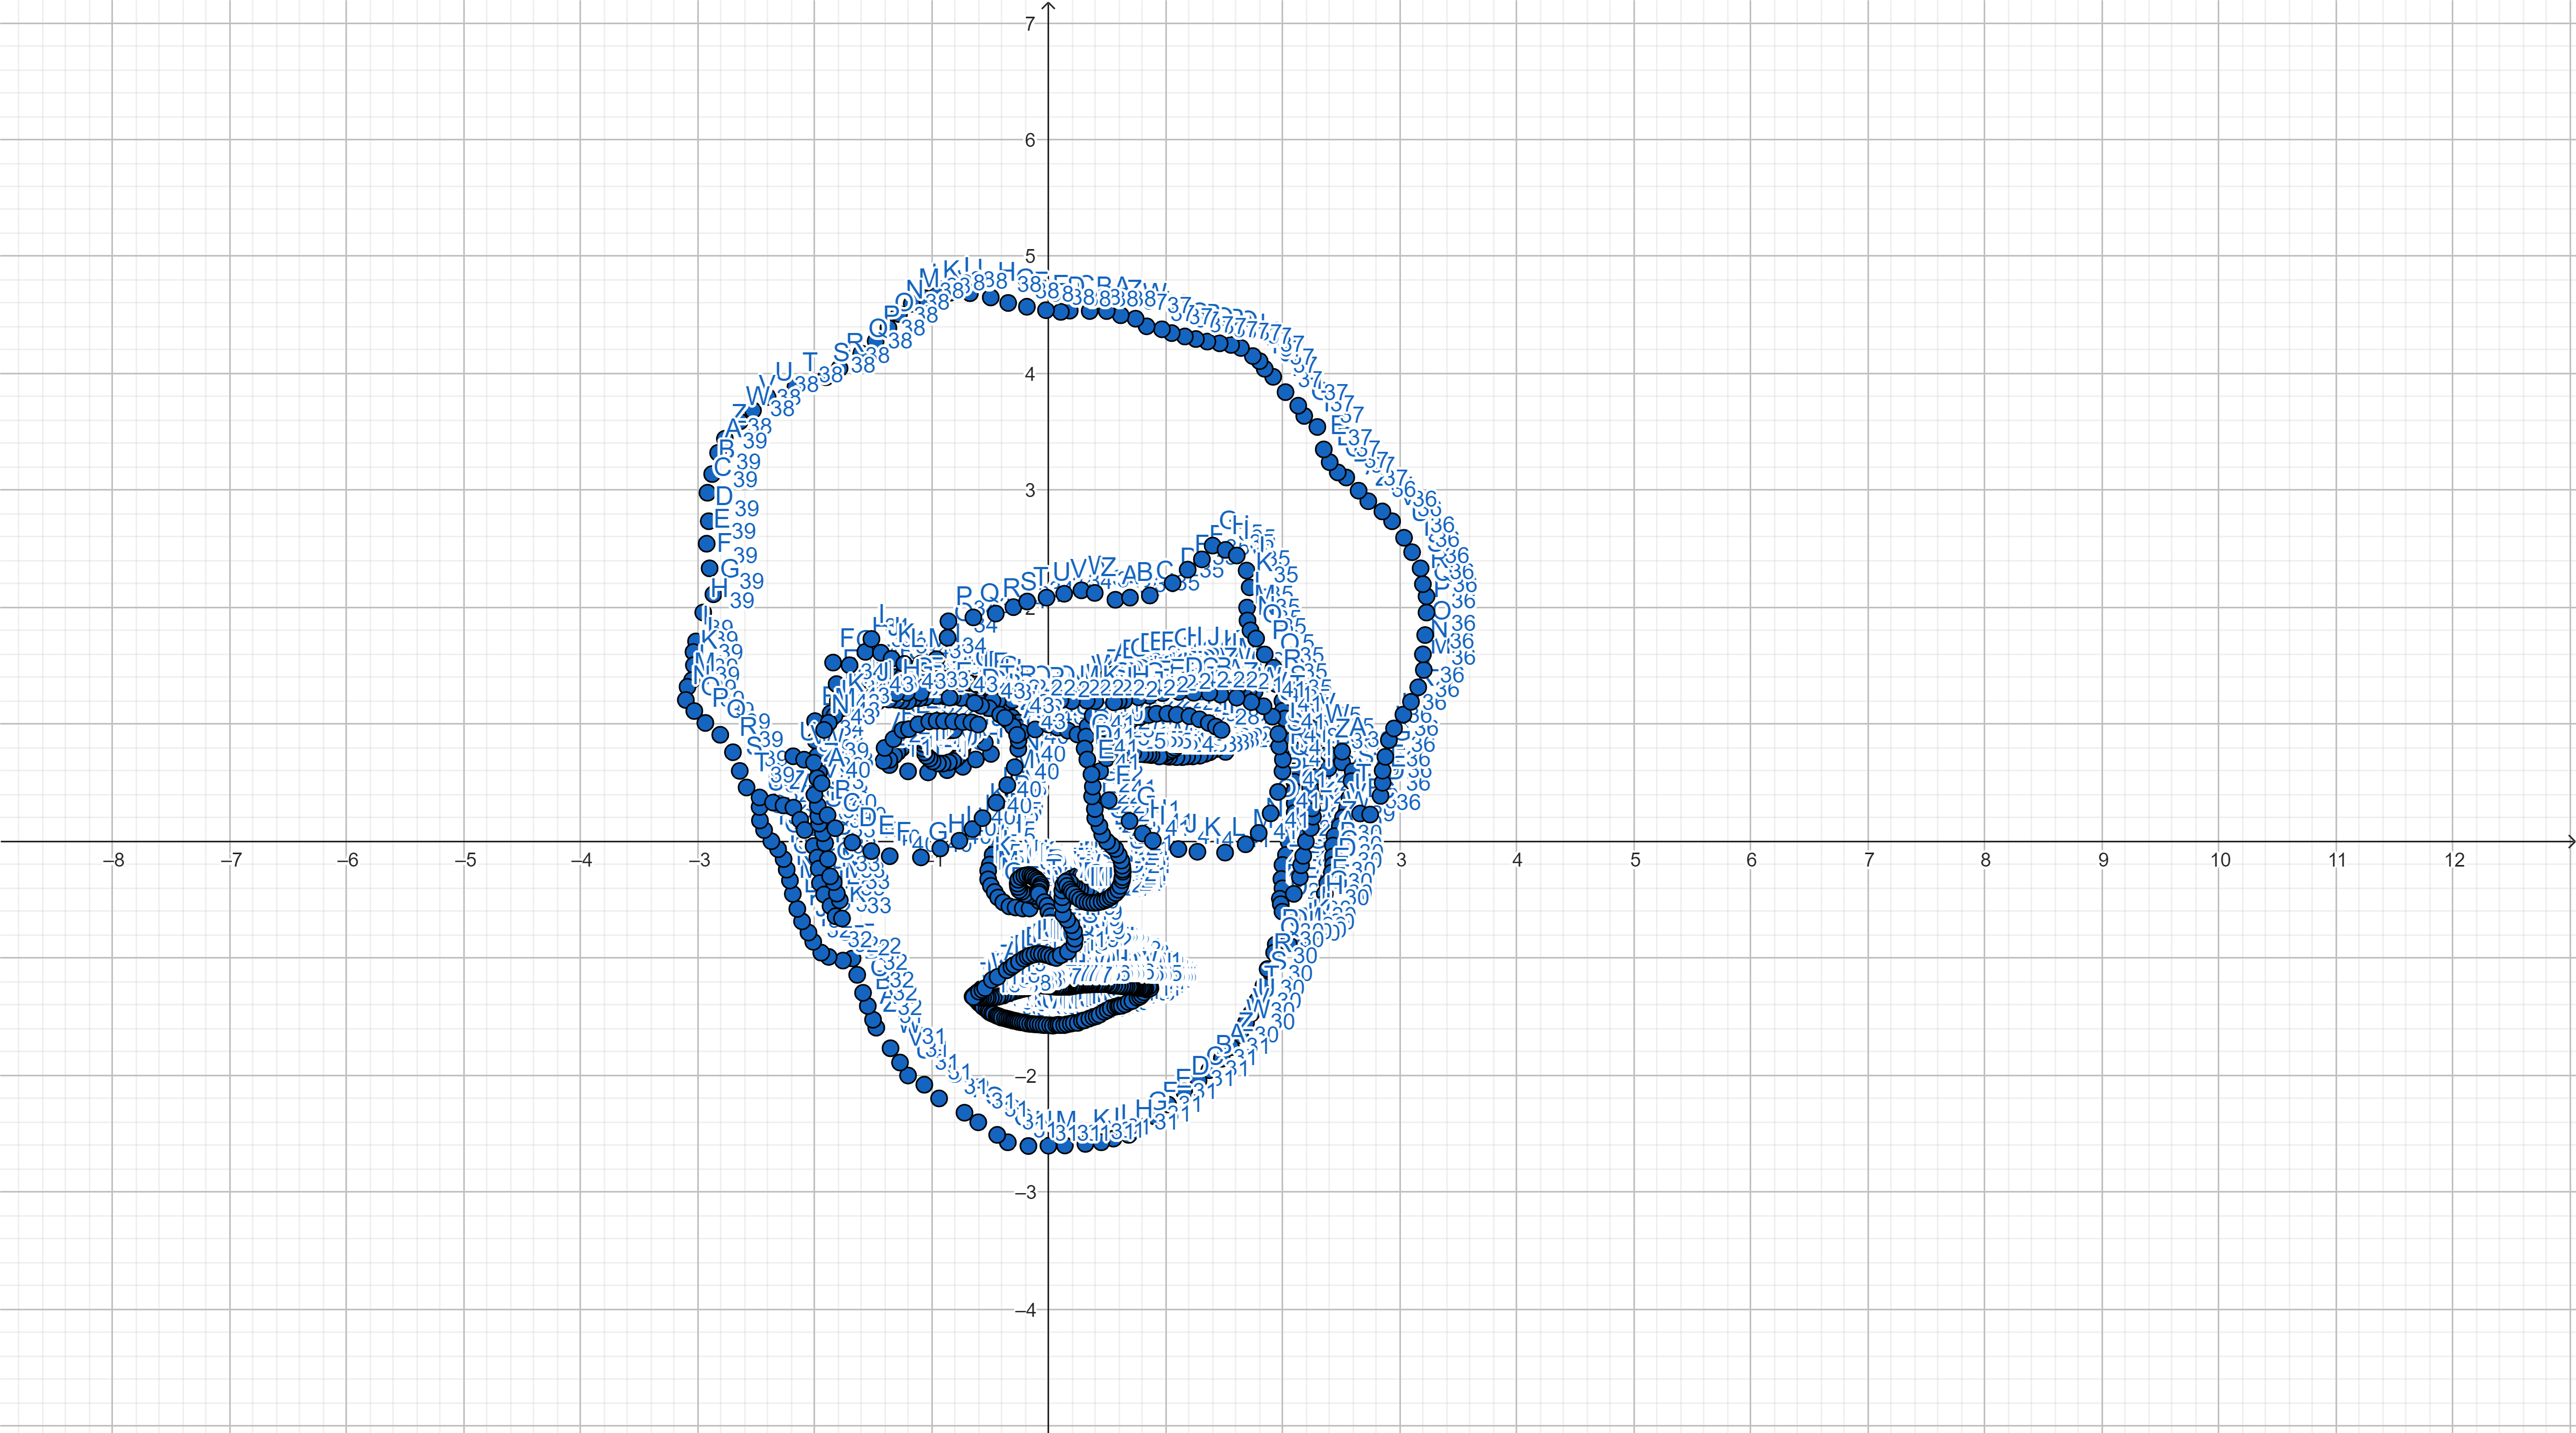


%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:190;         % Time array

initPose = [-1.3588966874359718;0.6532906325081589;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
 waypoints = [-1.3588966874359718,0.6532906325081589;
-1.2,0.6;
-1.0290101702896464,0.5909120910841288;
-0.8658662927191011,0.6101054884453694;
-0.7315125111904167,0.6388955844872304;
-0.6211504763632831,0.7012741259112624;
-0.49159504417490896,0.749257619314364;
-0.5443768869183206,0.8452246061205672;
-0.6211504763632831,0.902804798204289;
-0.7325381615806876,0.9390636572488231;
-0.7761519222539672,0.9473710402342097;
-0.760229438198643,0.91621835403901;
-0.7373841349888298,0.8760660029429749;
-0.7311535977497898,0.8393750614241842;
-0.7346150073270343,0.7950690188354557;
-0.7449992360587675,0.758378077316665;
-0.765075411606785,0.7306868006987097;
-0.7879207148165982,0.7078414974888966;
-0.8149197095191046,0.6884576038563279;
-0.8516106510378953,0.676688811293697;
-0.9049163585274593,0.6656123006465148;
-0.9450687096234945,0.6676891463928615;
-0.989374752212223,0.6843039123636346;
-1.0163737469147294,0.7085337794043455;
-1.041295895870889,0.7299945187832608;
-1.0606797895034579,0.7604549230630117;
-1.0696794544042934,0.793684455004558;
-1.0752177097278843,0.8352213699314909;
-1.07175630015064,0.863604928464895;
-1.0766022735587821,0.9009881518991346;
-1.0399113320399913,0.9127569444617656;
-0.9969898532821607,0.9286794285170898;
-0.9616834755942677,0.9362945295870275;
-0.9173774330055392,0.9425250668260675;
-0.8723791085013619,0.9480633221496586;
-0.8384572946443666,0.9508324498114541;
-0.8066123265337181,0.9522170136423519;
-1.1131767085211444,0.8841320077741495;
-1.1478027401105795,0.8610479867145263;
-1.1824287717000146,0.8402723677608654;
-1.226288411713299,0.821805150913167;
-1.2586060411967717,0.7941043256416191;
-1.2909236706802445,0.7617866961581466;
-1.3186244959517925,0.7340858708865989;
-1.3601757338591147,0.6971514371912018;
-1.409482403178664,0.6882311941524234;
-1.4,0.8;
-1.324202326884557,0.8752971679588497;
-1.2471751611995574,0.9523243336438487;
-1.1921557571388433,0.9605772442529558;
-1.1123776212508076,1.001841797298491;
-1.0188446343475936,1.026600529125812;
-0.9555723196777725,1.0321024695318834;
-0.8923000050079513,1.0293514993288477;
-0.8125218691199158,1.026600529125812;
-0.7299927630288445,1.0210985887197408;
-0.6584675377499162,1.018347618516705;
-0.6,1;
-0.463148653334381,1.1338883670442037;
-0.5154170871920595,1.1669000094806319;
-0.6,1.2;
-0.6694714185620589,1.216417473135274;
-0.7464985842470587,1.2274213539474168;
-0.8180238095259871,1.2356742645565237;
-0.8867980646018798,1.2411762049625952;
-0.9610742600838439,1.243927175165631;
-1.0491053065809866,1.232923294353488;
-1.101373740438665,1.224670383744381;
-1.148140233890272,1.224670383744381;
-1.2,1.2;
-1.2554280718086646,1.2054135923231313;
-1.3021945652602716,1.2109155327292027;
-1.362715909727057,1.2136665029322384;
-1.4534979264272354,1.19991165191706;
-1.511268300690985,1.1806548604958103;
-1.5607857643456278,1.1751529200897388;
-1.6268090492184848,1.1613980690745604;
-1.690081363888306,1.1503941882624178;
-1.7423497977459845,1.131137396841168;
-1.690081363888306,1.1971606817140243;
-1.6323109896245562,1.2576820261808093;
-1.5910464365790193,1.2906936686172366;
-1.5625422739760781,1.3111810354881004;
-1.5393826418611882,1.3361221777656738;
-1.511769234339589,1.361954075124589;
-1.4752482760045704,1.3860044623208205;
-1.4,1.4;
-1.3301089946951896,1.4070619337555315;
-1.2466100715735997,1.4090037691769637;
-1.1669948192948745,1.405120098334099;
-1.1,1.4;
-1.0232989981088823,1.405120098334099;
-0.93785823956586,1.3954109212269377;
-0.8757195060800257,1.391527250384073;
-0.799987924644165,1.374050731591182;
-0.7339655203154659,1.3682252253268852;
-0.6776522930939285,1.3565742127982914;
-0.6174553950295264,1.3429813648482651;
-0.5805605220223122,1.3371558585839682;
-0.5300728010650718,1.3216211752125098;
-0.47764324468639907,1.2827844667838635;
-0.4426902071006172,1.2575406063052434;
-0.405795334093403,1.2245294041408943;
-0.3805514736147828,1.1876345311336804;
-0.39996982782910606,1.160448835233628;
-0.4193881820434293,1.1235539622264141;
-0.3572719799025235,1.101584884938002;
-0.31329715394933316,1.0605417140483582;
-0.25759570774195867,1.0165668880951682;
-0.23121081217004444,0.9725920621419781;
-0.19603095140749216,0.9022323406168742;
-0.19603095140749216,0.8377359292188621;
-0.2,0.8;
-0.20775757166167624,0.7292646918676602;
-0.22827915710649843,0.6354517298341882;
-0.2488007425513206,0.5562970431184462;
-0.2751856381232348,0.4771423564027042;
-0.29863887863160304,0.4155776000682382;
-0.3308870843306093,0.3393545684160422;
-0.35140866977543145,0.2631315367638462;
-0.3689986001567076,0.2191567108106562;
-0.3836568754744377,0.1605236095397362;
-0.39831515079216784,0.11361712852300022;
-0.415905081173444,0.06671064750626424;
-0.4305633564911741,-0.0036490740188397596;
-0.44228997674535825,-0.05935052022621375;
-0.47746983750791056,-0.11505196643358774;
-0.5009230780162788,-0.19713830821287573;
-0.5155813533340089,-0.24990809935670372;
-0.5155813533340089,-0.3231994759453537;
-0.4921281128256407,-0.3789009221527277;
-0.4598799071266344,-0.4316707132965557;
-0.4305633564911741,-0.4785771943132917;
-0.38658853053798375,-0.5196203652029358;
-0.3338187393941553,-0.5548002259654877;
-0.2810489482503269,-0.5635951911561257;
-0.21948419191586035,-0.5723901563467637;
-0.16085109064493985,-0.5723901563467637;
-0.07876474886565116,-0.5078937449487517;
-0.10514964443756539,-0.4697822291226537;
-0.13626786570164307,-0.46480399314170534;
-0.1695987723310804,-0.4566964753129234;
-0.2,-0.45;
-0.22725223244686388,-0.42877058056934103;
-0.2497731153045918,-0.41615888616901353;
-0.2605831390763012,-0.3891338267397403;
-0.2632856450192286,-0.35940626136753967;
-0.25788063313337384,-0.3269761900524118;
-0.2326572443327186,-0.3053561425089932;
-0.2065330202177542,-0.2927444481086657;
-0.18221046673140803,-0.287339436222811;
-0.15608624261644363,-0.2882402715371201;
-0.13987120695887953,-0.2963477893659021;
-0.12635867724424277,-0.3080586484519205;
-0.10744113564375131,-0.3188686722236298;
-0.09302777061480544,-0.33328203725257555;
-0.08221774684309603,-0.3476954022815213;
-0.06600271118553193,-0.36931544982493986;
-0.06870521712845927,-0.38823299142543116;
-0.07320939370000486,-0.4044480270829951;
-0.0804160762144778,-0.4314730865122684;
-0.08311858215740514,-0.44858895748414146;
-0.03433111291577713,-0.517720599951809;
-0.01064375821848462,-0.5500215381753893;
0,-0.6;
0.01950378412352403,-0.6383107693198422;
0.015196992360379937,-0.6942990622407148;
0.006583408834091751,-0.7502873551615874;
0,-0.8;
0.015196992360379937,-0.8579571492401885;
0.043191138820816544,-0.9053318586347731;
0.06257170175496496,-0.9419395886214974;
0.08410566057068543,-0.991467693897654;
0.04749793058396064,-0.989314298016082;
0.020602215149172445,-0.9812679032074857;
-0.008822360855539705,-0.9702336872057188;
-0.04008597286054636,-0.9647165792048353;
-0.07502765686614203,-0.9628775432045409;
-0.1081303048714432,-0.9610385072042464;
-0.13939391687644986,-0.9720727232060133;
-0.17249656488175102,-0.9941411552095472;
-0.2,-1;
-0.2276676448905863,-1.0180486232133754;
-0.2515751128944149,-1.0419560912172037;
-0.2809996888991271,-1.0529903072189706;
-0.31042426490383923,-1.065863559221032;
-0.3398488409085514,-1.0879319912245657;
-0.37662956091444155,-1.1136784952286884;
-0.39869799291797564,-1.1357469272322223;
-0.4226054609218043,-1.150459215234578;
-0.44835196492592744,-1.161493431236345;
-0.47593750493034503,-1.1725276472381119;
-0.5,-1.2;
-0.5142829668349502,-1.2143528449964427;
-0.5246133022200975,-1.2246831803815899;
-0.5358044988873405,-1.2358743770488327;
-0.55,-1.25;
-0.5710998114532605,-1.2599784929475093;
-0.5865953145309815,-1.2754739960252302;
-0.6072559853012761,-1.2901086378208553;
-0.6193080432506147,-1.3012998344880982;
-0.6339426850462401,-1.3116301698732453;
-0.6485773268418654,-1.325403950386775;
-0.6313601011999532,-1.3383168696182088;
-0.6199179032844375,-1.3510036631109883;
-0.6063997767817947,-1.3619871408943853;
-0.5979509477176429,-1.374660384490613;
-0.5861225870278304,-1.386488745180425;
-0.5675351630866965,-1.3991619887766527;
-0.5447233246134867,-1.4202840614370318;
-0.5582414511161296,-1.4135249981857105;
-0.5295154322980136,-1.4346470708460897;
-0.5134626570761252,-1.4498549631615625;
-0.5007894134798975,-1.4608384409449597;
-0.48220198953876353,-1.4692872700091113;
-0.4686838630361207,-1.4752014503540174;
-0.4433373758436654,-1.487874693950245;
-0.42897436643460735,-1.4920991084823207;
-0.41376647411913414,-1.498858171733642;
-0.3977136988972458,-1.5064621178913786;
-0.3723672117047904,-1.5106865324234544;
-0.35377978776365654,-1.5166007127683605;
-0.3360372467289378,-1.5199802443940211;
-0.3182947056942191,-1.5258944247389272;
-0.3022419304723307,-1.5301188392710032;
-0.2878789210632727,-1.5326534879902487;
-0.2718261458413843,-1.5360330196159093;
-0.2566182535259111,-1.5411023170544003;
-0.23972059539760754,-1.5444818486800609;
-0.21944340564364329,-1.5470164973993064;
-0.2,-1.55;
-0.18142367485496028,-1.5554653264634581;
-0.15607718766250495,-1.5588448580891188;
-0.13242046628287996,-1.559689740995534;
-0.11552280815457641,-1.5622243897147794;
-0.09186608677495144,-1.5622243897147794;
-0.06820936539532646,-1.5664488042468552;
-0.042017995296455946,-1.5689834529661006;
-0.017516391010415792,-1.5698283358725158;
0.012899393620530608,-1.570673218778931;
0.03824588081298594,-1.5740527504045916;
0.06697189963110199,-1.5689834529661006;
0.08471444066582072,-1.5664488042468552;
0.10217291413170783,-1.5695211264675841;
0.13380865683331628,-1.5695211264675841;
0.15927157169070846,-1.562576695142841;
0.19013571091178988,-1.556403867298625;
0.21637022924970906,-1.5510026429349357;
0.25,-1.55;
0.2858145424971422,-1.5332557628828143;
0.3089626469129533,-1.5278545385191251;
0.34908602790035914,-1.5131940723891117;
0.3830365810435487,-1.5008484167006795;
0.411585909823049,-1.4923607784148822;
0.43627722119991413,-1.4800151227264497;
0.4756289987067929,-1.4560954148301122;
0.5057215344473474,-1.4414349487000988;
0.5327276562657935,-1.4236880686479774;
0.5699729676681398,-1.4125495961820158;
0.5935796907444844,-1.4075421094688518;
0.6071714403945009,-1.405396043734639;
0.6257706767576815,-1.4039653332451634;
0.6565309522814032,-1.3918042940846225;
0.6851451620709118,-1.3724897024767047;
0.7173361480841088,-1.3624747290503767;
0.7606154291312971,-1.3359616226442983;
0.7827492328990998,-1.3254322336661204;
0.7975101795290445,-1.308914031484992;
0.8154341861511202,-1.2895842204219696;
0.8396942561688892,-1.2649141390992158;
0.8564823110004854,-1.2584399255267957;
0.8709173101906934,-1.2541750394024163;
0.8659684245369628,-1.2289667680032952;
0.8518631325220817,-1.2210325412449248;
0.8386394212581307,-1.2130983144865544;
0.8218893869904594,-1.206927249230044;
0.8104288372283686,-1.1989930224716736;
0.7875077377041869,-1.1901772149623733;
0.775165607191166,-1.1787166652002825;
0.7637050574290751,-1.170782438441912;
0.749599765414194,-1.1619666309326118;
0.7381392156521032,-1.152269242672381;
0.7160996968788516,-1.1416902736612207;
0.7072838893695509,-1.13111130465006;
0.6834812090944391,-1.1187691741370394;
0.6649680133249077,-1.1046638821221586;
0.6394021715479359,-1.0861506863526276;
0.6208889757784044,-1.079098040345187;
0.6085468452653835,-1.0711638135868167;
0.5935599724995724,-1.0605848445756563;
0.5688757114735306,-1.0473611333117054;
0.5494809349530692,-1.0403084873042652;
0.5362572236891181,-1.0341374220477548;
0.5247966739270273,-1.0270847760403143;
0.507165058908426,-1.0182689685310138;
0.4835034164056455,-0.9995990313987934;
0.4541017158357985,-0.9867357873994855;
0.4400773923781093,-0.9815912257175514;
0.42482276765758964,-0.9768241554923891;
0.40480107271190763,-0.9691968431321295;
0.38859303394635547,-0.9644297729069672;
0.37238499518080337,-0.9606161167268373;
0.3552235423702188,-0.9587092886367724;
0.3380620895596342,-0.9587092886367724;
0.3209006367490496,-0.9568024605467076;
0.303739183938465,-0.9568024605467076;
0.28085724685768554,-0.9520353903215453;
0.263695794047101,-0.9558490465016751;
0.2446275131464514,-0.9606161167268373;
0.2284194743808993,-0.9653831869519997;
0.21316484966037966,-0.9691968431321295;
0.18837608448953524,-0.9749173274023242;
0.1693078035888857,-0.978730983582454;
0.15405317886836606,-0.9844514678526488;
0.13879855414784642,-0.9901719521228435;
0.12449734347235926,-0.9920787802129084;
0.1,-1;
0.11591661706706696,-1.0063799908883952;
0.12354392942732678,-1.031168756059239;
0.12545075751739174,-1.0588177633651803;
0.12545075751739174,-1.0769326302207969;
0.12831099965248915,-1.1017213953916407;
0.12545075751739174,-1.118882848202225;
0.1273575856074567,-1.139857957192939;
0.12831099965248915,-1.1646467223637829;
0.12831099965248915,-1.1799013470843023;
0.12926441369752165,-1.1951559718048215;
0.12926441369752165,-1.2113640105703731;
0.1311712417875866,-1.2285254633809575;
0.155960006958431,-1.2323391195610873;
0.17407487381404807,-1.2332925336061198;
0.1893294985345677,-1.2304322914710224;
0.20297592997658273,-1.2291916753427894;
0.21657628453660527,-1.2284565210422476;
0.2320145248479822,-1.2233104409384554;
0.24782034230963002,-1.218899515135205;
0.26,-1.22;
0.27575620573021686,-1.216326475083309;
0.29266475464267727,-1.2170616293838505;
0.3092057264048669,-1.215958897933038;
0.32170334951407675,-1.2148561664822255;
0.3437579785303295,-1.2144885893319546;
0.35515287018872677,-1.2144885893319546;
0.3672829161476658,-1.2126507035806002;
0.3852941965109389,-1.210445240678975;
0.39521877956825263,-1.210445240678975;
0.42168433438775593,-1.2097100863784331;
0.4444741177045505,-1.210445240678975;
0.46211782091755266,-1.2108128178292459;
0.48711306713597247,-1.2115479721297875;
0.5140695706310727,-1.2160168058610912;
0.5503917074849108,-1.2217822244093193;
0.573453381677824,-1.2252414755382564;
0.603433558128611,-1.2275476429575476;
0.6259186904667012,-1.2298538103768388;
0.6437914879662089,-1.2310068940864844;
0.659934659901248,-1.2310068940864844;
0.6876086689327437,-1.229277268522016;
0.6997160478840231,-1.2338896033605984;
0.7187419290931765,-1.235619228925067;
0.7325789336089243,-1.2361957707798896;
0.7487221055439635,-1.2379253963443582;
0.7683245286079395,-1.2396550219088267;
0.7821615331236874,-1.2425377311829406;
0.7942689120749669,-1.2425377311829406;
0.8075293747358918,-1.2442673567474092;
0.8190602118323483,-1.248303149731169;
0.8328972163480962,-1.2471500660215231;
0.8588415998151234,-1.2390784800540038;
0.827131797799868,-1.254068568279397;
0.8132947932841201,-1.2552216519890427;
0.8,-1.25;
0.783891158688156,-1.2534920264245741;
0.7654418193338255,-1.2506093171504602;
0.75,-1.25;
0.7389208940119754,-1.2431142730377636;
0.7256604313510504,-1.2436908148925863;
0.7129765105449481,-1.2442673567474092;
0.703751840867783,-1.2431142730377636;
0.6904913782068579,-1.241961189328118;
0.6685827877235905,-1.241384647473295;
0.6512865320789056,-1.2396550219088267;
0.633413734579398,-1.2373488544895355;
0.6103520603864849,-1.2361957707798896;
0.5884434699032175,-1.2333130615057757;
0.5613460027265446,-1.23215997779613;
0.536554702969163,-1.2287007266671932;
0.5192584473244782,-1.2240883918286105;
0.49446714756709664,-1.2188995151352053;
0.4771708919224118,-1.2177464314255597;
0.4523795921650302,-1.220052598844851;
0.4373895039396367,-1.2183229732803824;
0.42066979014977474,-1.220052598844851;
0.3993377415213301,-1.220052598844851;
0.3751229836187714,-1.220052598844851;
0.3607094372482007,-1.2212056825544966;
0.3486020582969213,-1.2217822244093193;
0.33015271894259085,-1.222935308118965;
0.31516263071719736,-1.222935308118965;
0.3013256262014495,-1.2240883918286105;
0.2846059124115875,-1.225818017393079;
0.26846274047654833,-1.2287007266671932;
0.25404919410597765,-1.2281241848123703;
0.23905910588058413,-1.229277268522016;
0.22637518507448193,-1.2338896033605984;
0.21196163870391124,-1.2361957707798896;
0.18717033894652968,-1.2390784800540038;
0.19581846676887207,-1.238501938199181;
0.17563950185007313,-1.241961189328118;
0.1623790391891481,-1.2402315637636494;
0.1479654928185774,-1.241961189328118;
0.13643465572212088,-1.2390784800540038;
0.12720998604495565,-1.2396550219088267;
0.11683223265814474,-1.241961189328118;
0.1029952281423969,-1.2431142730377636;
0.08476080191286176,-1.2427704017790013;
0.06678991616989399,-1.2419146453150507;
0.04282873517927031,-1.240203132387149;
0.02314633650840085,-1.2384916194592472;
0.0068869636933347736,-1.2367801065313457;
-0.014506947905436376,-1.2333570806755423;
-0.03761237243210922,-1.2325013242115914;
-0.05643901463902783,-1.23078981128369;
-0.07526565684594644,-1.229934054819739;
-0.09922683783657013,-1.2316455677476406;
-0.12062074943534128,-1.2316455677476406;
-0.14372617396201412,-1.235068593603444;
-0.16854311141658865,-1.2384916194592472;
-0.19135044333899565,-1.2561095721778384;
-0.21733930555278996,-1.2601078586722683;
-0.2423285961429768,-1.266105288413913;
-0.2613204569915188,-1.2721027181555578;
-0.28531017595809816,-1.2781001478972025;
-0.30830032330107005,-1.286096720886062;
-0.3332896138912569,-1.2920941506277068;
-0.35,-1.3;
-0.38726648156606047,-1.3170834412178931;
-0.4142549154034622,-1.3220812993359303;
-0.4342463478756117,-1.328078729077575;
-0.4682317830782658,-1.3330765871956123;
-0.49222150204484516,-1.3350757304428271;
-0.517210792635032,-1.3350757304428271;
-0.5352030818599666,-1.3350757304428271;
-0.5581932292029385,-1.3350757304428271;
-0.5781846616750879,-1.3350757304428271;
-0.5941778076528075,-1.33007787232479;
-0.6071722387597046,-1.3200821560887155;
-0.6181675266193871,-1.3239404798041277;
-0.6303734952576453,-1.326381673531779;
-0.6401382701682518,-1.3288228672594307;
-0.5935156205541651,-1.2837636614802934;
-0.5647389628006858,-1.2693753326035542;
-0.5417176365979025,-1.2526848711065366;
-0.4835887879358745,-1.183620892498188;
-0.4346684697549599,-1.157721900520057;
-0.35639596066549645,-1.1001685850130998;
-0.3166841729656952,-1.0725429935697604;
-0.29308731360784224,-1.0552769989176731;
-0.25222445959790174,-1.0288024737844728;
-0.20675734034740464,-1.0011768823411333;
-0.17798068259392544,-0.9839108876890462;
-0.15495935639114208,-0.9741268240528634;
-0.11985183393189745,-0.9649182935717503;
-0.08416877831758325,-0.958587428865985;
-0.055967653719173636,-0.9614650946413329;
-0.0214356644149986,-0.9695225588123069;
0.0038877944080630902,-0.974702357207933;
0.03554211793689021,-0.9867885534643941;
0.06662090831064774,-0.9954215507904376;
0.10518162970030986,-0.9718246914325852;
0.16645905233826883,-0.9409421735372528;
0.21997057218026708,-0.8762305681469308;
0.2249483879795227,-0.830185772003817;
0.21872611823045315,-0.7692075284629366;
0.19508149318398882,-0.7156960086209395;
0.16023678258919927,-0.6671623045781979;
0.12539207199440972,-0.6198730544852703;
0.11792534829552624,-0.5377390937975538;
0.11792534829552624,-0.47676085025667336;
0.11792534829552624,-0.4195159685652346;
0.12663652594422362,-0.37222671847230693;
0.15650342073975754,-0.3373820078775181;
0.20005930898324448,-0.31498183678086816;
0.2423707432769175,-0.295070573583846;
0.27721545387170704,-0.29133721173440436;
0.3,-0.3;
0.32948251976389137,-0.3037817512325432;
0.35437159876016966,-0.31871519863030984;
0.3705495001077505,-0.33240419207826255;
0.3805051317062618,-0.35107100132547087;
0.3892163093549592,-0.382182350070818;
0.3643272303586809,-0.40084915931802634;
0.3220157960650079,-0.4132936988161652;
0.2709931841226375,-0.40707142906709576;
0.24485965117654532,-0.39089352771951524;
0.21997057218026708,-0.37222671847230693;
0.20005930898324448,-0.3535599092250986;
0.18139249973603577,-0.3460931855262153;
0.14593082356532713,-0.3468967379324161;
0.16,-0.38;
0.18553667766085885,-0.4100975689359227;
0.19859818273491717,-0.43032183485704484;
0.21671575428925613,-0.44801806753802664;
0.24578813655086984,-0.4758264331795696;
0.2702257912055596,-0.49520802135397823;
0.30182620670731364,-0.5129042540349601;
0.3325839444623542,-0.5204883537553809;
0.3612349878506112,-0.5238590647422345;
0.39199272560565174,-0.5242804036155913;
0.42,-0.52;
0.453508201115733,-0.5137469317816735;
0.4830019222507034,-0.5032134599477558;
0.5049115436652528,-0.49141597149376787;
0.5322985704334396,-0.4762477720529263;
0.5495734642410651,-0.45939421711865785;
0.5752751355158251,-0.44043396781760585;
0.5967634180570178,-0.4130469410494197;
0.6136169729912866,-0.3789184923075261;
0.6287851724321286,-0.33004318299814767;
0.6317345445456256,-0.30434151172338836;
0.6351052555324793,-0.2575728967807935;
0.6329985611656958,-0.23987666409981162;
0.629627850178842,-0.20616955423127475;
0.6226744125554237,-0.163004666848561;
0.6006620142272978,-0.11550422835102737;
0.5716983322166058,-0.06336960073178313;
0.5392590083646309,-0.033247371440664246;
0.5,0;
0.45951364724119914,0.05933154734939516;
0.43556345986038447,0.13118210949183734;
0.4,0.2;
0.39664440536656065,0.27787700719932346;
0.372694217985746,0.3856528504129867;
0.3786817648309497,0.4694785062458359;
0.44155100670558817,0.6012045368403133;
0.49843270173502296,0.7119741534765782;
0.5433393030740505,0.8227437701128433;
0.6092023183712908,0.912556972790896;
0.7050030678945495,0.9724324412429312;
0.8337353250664283,0.9903950817785417;
0.965461355660909,0.9993764020463469;
1.0762309722971768,0.9903950817785417;
1.16305040155263,0.9903950817785417;
1.2349009636950738,0.9694386678203294;
1.321720392950527,0.9514760272847188;
1.4055460487833784,0.912556972790896;
1.4414713298546005,0.8766316917196749;
1.4893717046162298,0.8047811295772327;
1.5133218919970444,0.7658620750834099;
1.432490009586795,0.789812262464224;
1.378602087979962,0.7628683016608088;
1.3383820157716948,0.748945968973332;
1.2935211660009351,0.7334767104316912;
1.2331910576885343,0.7272890070150347;
1.1852363562094463,0.7272890070150347;
1.143469358147015,0.7211013035983784;
1.093967730813763,0.7211013035983784;
1.032090696647198,0.7241951553067066;
1.0042460312722437,0.730382858723363;
0.982589069313946,0.7427582655566757;
0.9767574163738383,0.759476279780569;
1.00817238676874,0.7647121081797191;
1.0369694429640666,0.7699479365788693;
1.0644575420596054,0.782383029026851;
1.0827829414566315,0.8007084284238765;
1.1017628194035511,0.8229606991202646;
1.1187792617007897,0.8439040127168652;
1.129905397048984,0.8733555474620848;
1.1371046610978157,0.906733953506667;
1.1377591396477094,0.9381489239015679;
1.1377591396477094,0.9571288018484873;
1.14,0.98;
1.1324933937732866,0.9870158543478986;
1.1085088648631283,0.9879564241090812;
1.0628912314457684,0.9931295577955859;
1.0483124001474369,0.9950106973179511;
1.0285604351626008,0.9973621217209078;
1.009749039938947,0.9997135461238644;
1,1;
0.9871753656705629,0.9997135461238644;
0.9472011508202989,1.0001838310044557;
0.9312114648801934,0.9997135461238644;
0.9109892150147658,0.9950106973179511;
0.8855938314628334,0.9945404124373598;
0.8691338606421366,0.9954809821985425;
0.8578470235079445,0.9950106973179511;
0.8122293900905846,0.9898375636314466;
0.8070562564040799,0.979021011377846;
0.8,0.94;
0.7957694192698876,0.9056565700055992;
0.8056454017623058,0.8713257737224324;
0.8164619540159066,0.8440492506481354;
0.8329219248366034,0.8195944368573864;
0.8497629147508571,0.7986189213352235;
0.8922555872297994,0.768024197150386;
0.9347482597087415,0.7544265419571248;
0.9466462080028454,0.7272312315706024;
0.8803576389356955,0.7391291798647059;
0.8548620354483302,0.7425285936630213;
0.8242673112634917,0.7442283005621789;
0.7868737594820225,0.7476277143604941;
0.7256843111123458,0.7595256626545976;
0.6865910524317189,0.762925076452913;
0.6389992592553035,0.762925076452913;
0.5999060005746767,0.7561262488562824;
0.5659118625915229,0.7510271281588095;
0.5353171384066845,0.7595256626545976;
0.49282446592774226,0.7850212661419623;
0.4877253452302692,0.8513098352091104;
0.47922681073448076,0.910799576679628;
0.4758273969361654,1.0076828699316136;
0.46902856933953463,1.0773708527970771;
0.4673288624403769,1.1283620597718063;
0.4588303279445885,1.177653559847378;
0.45033179344880003,1.2184465254271615;
0.40104029337322705,1.2405427151162107;
0.3619470346926002,1.2388430082170532;
0.30245729322208104,1.2405427151162107;
0.24976637934819268,1.2252453530237921;
0.30415700012123875,1.283035387595152;
0.3568479139951271,1.301732163485886;
0.42823560375975006,1.3493239566623;
0.5,1.4;
0.5642121556923653,1.430909887821867;
0.642398673053619,1.4479069568134433;
0.7239846042131881,1.4836008016957538;
0.8,1.5;
0.9,1.5;
1.014634483969153,1.5294928879730103;
1.1285148462127181,1.5362917155696407;
1.211800484271445,1.5430905431662714;
1.3001852430276448,1.5430905431662714;
1.43616179496026,1.515895232779749;
1.5092491916240407,1.4802013878974385;
1.5687389330945598,1.444507543015128;
1.6401266228591826,1.4003151636370292;
1.687718416035598,1.3663210256538765;
1.7234122609179094,1.3357263014690388;
1.7625055195985366,1.283035387595152;
1.714913726422121,1.2983327496875707;
1.6724210539431787,1.3102306979816742;
1.621429846968448,1.3238283531749353;
1.5687389330945598,1.3374260083681966;
1.5313453813130906,1.3510236635614576;
1.4701559329434137,1.3561227842589305;
1.4208644328678408,1.3612219049564036;
1.3409782086074293,1.3612219049564036;
1.2797887602377525,1.3527233704606152;
1.216899604968918,1.3510236635614576;
1.1727072255908182,1.3374260083681966;
1.123415725515245,1.3357263014690388;
1.07582393233883,1.325528060074093;
1.019733604666626,1.3238283531749353;
0.9874391735826299,1.3136301117799896;
0.938147673507057,1.306831284183359;
0.9,1.3;
0.8395646733559109,1.29153392209094;
0.7970720008769687,1.2847350944943094;
0.7562790352971842,1.2711374393010484;
0.6950895869275073,1.2660383186035755;
0.6508972075494074,1.2558400772086296;
0.6118039488687805,1.2473415427128414;
0.5659118625915229,1.2388430082170532;
0.5370168453058423,1.2371433013178956;
0.5047224142218462,1.2286447668221072;
0.48262622453279613,0.9702893181501455;
0.5421159660033152,0.915898697377101;
0.6440983799527766,1.0076828699316136;
0.7052878283224535,1.0399773010156088;
0.7817746387845496,1.0637731976038158;
0.8548620354483302,1.0807702665953922;
0.9228503114146377,1.0926682148894957;
1.0163341908683106,1.0926682148894957;
1.096220415128722,1.0841696803937075;
1.2050016566748143,1.0705720252004465;
1.2899870016326986,1.045076421713082;
1.3698732258931101,1.0127819906290865;
1.431062674262787,0.982187266444249;
1.4786544674392021,0.953292249158569;
2.0344586234637667,0.958391369856042;
2.0838620509103096,0.8665098052068113;
2.0942477053949426,0.786020982950908;
2.089054878152626,0.7081285743161629;
2.089054878152626,0.5990792022275199;
2.1020369462584174,0.5108011391081421;
2.1020369462584174,0.4303123168522388;
2.1046333598795757,0.326455772005912;
2.1046333598795757,0.24596694975000977;
2.0942477053949426,0.16028530025179022;
2.076072810046835,0.09537495972283604;
2.0527050874564106,-0.0032887578811743494;
2.0293373648659863,-0.11493454359097557;
2,-0.2;
1.9903911605486126,-0.32005121966247085;
2,-0.4;
1.9774090924428214,-0.48881810503775175;
1.9851983333062961,-0.5355535502185987;
2,-0.6;
2.096844119016101,-0.44727548709922105;
2.1487723914392656,-0.3044727379355218;
2.1591580459238986,-0.2032126067103533;
2.1773329412720064,-0.12272378445445008;
2.2,0;
2.2422432818009628,0.11614626869210137;
2.26041817714907,0.21221357267495358;
2.252628936285596,0.2823167404462241;
2.2500325226644375,0.39396252615602534;
2.2370504545586463,0.45887286668497956;
2.301960795087602,0.5575365842889899;
2.3928352718281407,0.6276397520602605;
2.5096738847802618,0.6769716108622656;
2.6,0.6;
2.5901627070361677,0.5159939663504592;
2.57198781168806,0.3705948035656018;
2.551216502718794,0.28491315406738227;
2.5174631256437365,0.2044243318114791;
2.488902575810996,0.1291283367978922;
2.444763544251306,0.04604310092083084;
2.4317814761455145,-0.034445721335072364;
2.4317814761455145,-0.1279166116967664;
2.4317814761455145,-0.20061619308919512;
2.4213958216608815,-0.2655265336181493;
2.3824496173435077,-0.3564010103586852;
2.361678308374242,-0.44727548709922105;
2.3331177585415013,-0.5407463774609151;
2.309750035951077,-0.5926746498840785;
2.2734002452548614,-0.6861455402457726;
2.2500325226644375,-0.7380738126689359;
2.2,-0.8;
2.151368805060424,-0.8237554621671555;
2.099440532637259,-0.8575088392422117;
2.055301501077569,-0.8834729754537933;
1.9877947469274544,-0.8808765618326351;
1.942821811487103,-0.880170912292964;
1.9288344068020808,-0.950107935718073;
1.8728847880619919,-1.0899819825682908;
1.8365175358809342,-1.2354509912925176;
1.7833653980778497,-1.3613376334577136;
1.7330107412117697,-1.4704393900008836;
1.6882510462196985,-1.5487688562370057;
1.6378963893536185,-1.6550731318431713;
1.559566923117494,-1.7585799265123325;
1.4812374568813698,-1.8564917593074852;
1.3749331812752008,-1.9544035921026377;
1.282616310354054,-2.043922982086777;
1.1595271491258585,-2.136239853007921;
1.0224505832126407,-2.2481390904880953;
0.9133488266694674,-2.351645885157257;
0.7874621845042674,-2.438367794204392;
0.6864077368786511,-2.5078151331370346;
0.5554640008649137,-2.539422241830005;
0.4516120723022944,-2.571029350522975;
0.31615303504670395,-2.584575254248534;
0.1400562866144364,-2.5981211579740924;
0,-2.6;
-0.1714994990734216,-2.602636459215945;
-0.3475962475056892,-2.571029350522975;
-0.4379022723427495,-2.5078151331370346;
-0.6,-2.4;
-0.7178509493376364,-2.3181724809792135;
-0.934585408946581,-2.196259347449186;
-1.0610138437184655,-2.078861515161011;
-1.2,-2;
-1.268717700843704,-1.88921886300319;
-1.3499931231970583,-1.7673057294731622;
-1.4719062567270897,-1.5912089810408998;
-1.498998064178208,-1.5234794624131067;
-1.544151076596738,-1.4060816301249317;
-1.584788787773415,-1.2931990990786097;
-1.6344571014337983,-1.1396788568556118;
-1.6750948126104754,-0.9997045183581724;
-1.7563702349638297,-1.017765723325584;
-1.8782833684938611,-0.9861586146326138;
-1.9419760178293113,-0.9501120745095816;
-2.010220873749371,-0.857299070458303;
-2.051167787301407,-0.778135037591036;
-2.1057636720374546,-0.682592239302955;
-2.146710585589491,-0.5761302640676648;
-2.184927704904724,-0.44782993493795614;
-2.209495853035946,-0.333178576992259;
-2.23679379540397,-0.24036557294098038;
-2.2640917377719934,-0.1502823631265041;
-2.310498239797634,-0.0656587417856324;
-2.3678239187704846,0.0025861141344254153;
-2.430609186216939,0.09812891242250635;
-2.4660965112953703,0.18002273952657571;
-2.468826305532173,0.29467409747227286;
-2.468826305532173,0.3765679245763422;
-2.3541749475864724,0.3328912167875052;
-2.2640917377719934,0.3083230686562844;
-2.1794681164311194,0.28921450899866824;
-2.1221424374582694,0.18548232800018033;
-2.0839253181430357,0.09812891242250635;
-2.007491079512569,-0.03836079941760927;
-1.97473354867094,-0.13663339194249252;
-1.9638143717237304,-0.23217619023057345;
-1.952895194776521,-0.3550169308866775;
-1.9174078696980899,-0.45328952341156076;
-1.862811984962042,-0.551562115936444;
-1.8191352771732037,-0.638915531514118;
-1.7645393924371557,-0.6580240911717342;
-1.7836479520947726,-0.5024258196740023;
-1.8082161002259942,-0.44510014070115383;
-1.835514042594018,-0.3468275481762706;
-1.8655417791988442,-0.29769125191382895;
-1.884650338856461,-0.1502823631265041;
-1.9092184869876827,-0.01379265128638846;
-1.9283270466452993,0.07083097005448323;
-1.961084577486928,0.15272479715855258;
-1.9665441659605327,0.21551006460500577;
-1.9720037544341376,0.3055932744194821;
-2,0.4;
-1.961726793996463,0.5878736673238228;
-1.9764356590011392,0.731285101119409;
-1.991144524005815,0.8636648861614886;
-1.9948217402569839,1.029139617464088;
-1.8624419552149007,1.095329509985128;
-1.8,1.2;
-1.810960927698535,1.3453802150646115;
-1.8403786577078867,1.5292410276230552;
-1.7006444401634655,1.5071777301160418;
-1.5645874388702132,1.6211714339022771;
-1.5131064113538475,1.7314879214373433;
-1.4322076538281299,1.6138170013999393;
-1.3402772475489053,1.5623359738835751;
-1.2336379762650047,1.5182093788695485;
-1.0902265424694144,1.5218865951207174;
-0.9578467574273312,1.5586587576324062;
-0.8622391348969377,1.74251957019085;
-0.8548847023945997,1.8822537877352672;
-0.6416061598267988,1.915348733995787;
-0.45039091476601173,1.948443680256307;
-0.29962504846808347,2.0036019240238403;
-0.18195412843067607,2.051405735289036;
-0.016479397128071914,2.0845006815495557;
0.13428646916985634,2.117595627810075;
0.28137511921661557,2.1470133578194264;
0.39536882300285403,2.124950060312413;
0.5718752030589651,2.066114600293711;
0.6969005555987106,2.0845006815495557;
0.8660525031524836,2.1028867628054;
1.0609449644644409,2.209526034089296;
1.1896475332553553,2.323519737875531;
1.3109956695439318,2.411772927903584;
1.4029260758231563,2.529443847940988;
1.5132425633582256,2.4926716854292996;
1.6088501858886193,2.444867874164104;
1.6934261596655058,2.3161653053731937;
1.7191666734236886,2.172753871577607;
1.6971033759166747,1.99992470777267;
1.7007805921678436,1.8896082202376039;
1.7265211059260266,1.8050322464607196;
1.7743249171912234,1.735165137688511;
1.847869242214603,1.5991081363952626;
1.9250907834891515,1.4851144326090273;
1.9471540809961654,1.3453802150646101;
2,1.2;
2.0023123247637002,1.1173928074921398;
2.020698406019545,1.0512029149711;
2.252363029843191,0.9703041574453848;
2.3075212736107256,0.8820509674173317;
2.3920972473876123,0.7496711823752522;
2.50976816742502,0.7680572636310966;
2.6635636666126112,0.2393321399721636;
2.7492997397685777,0.2304628910249949;
2.837992229240267,0.39010937207403124;
2.855730727134605,0.5024531920715012;
2.855730727134605,0.6059277631218025;
2.879382057660389,0.7241844157507183;
2.9089462208176187,0.8660923989054172;
2.9532924655534636,0.9666105536399957;
3.033115706077984,1.0848672062689115;
3.0981568650238898,1.1942546099506586;
3.160241607654072,1.3184240952110202;
3.20754426870564,1.466244910997165;
3.2,1.6;
3.2193699339685318,1.7648429588851773;
3.2309323804487,1.9574811097134237;
3.2309323804487,2.0954103062743616;
3.2,2.2;
3.18011636066309,2.334971542406516;
3.107522046683647,2.472900738967454;
3.038557448403176,2.596311072732503;
2.936925408831956,2.737869984992413;
2.853441947755597,2.82135344606877;
2.733661329689516,2.908466622844099;
2.6501778686131563,2.9992095153184;
2.544916113342964,3.1117307019865335;
2.472321799363521,3.155287290374198;
2.4033572010830504,3.242400467149527;
2.35254118129744,3.3512919381186883;
2.298095445812858,3.5436668701642065;
2.1855742591447216,3.63803947833748;
2.1347582393591114,3.725152655112809;
2.025866768389947,3.841303557479914;
1.9206050131197547,3.9719733226429077;
1.8480106991403125,4.040937920923379;
1.8044541107526468,4.106272803504876;
1.7463786595690924,4.14982939189254;
1.6447466199978722,4.218793990173009;
1.561263158921513,4.244202000065814;
1.4632608350492649,4.2587208628617015;
1.3579990797790726,4.273239725657589;
1.2599967559068246,4.295018019851422;
1.165624147733549,4.316796314045254;
1.0531029610654123,4.3458340396370305;
0.969619499989053,4.378501480927779;
0.8389497348260556,4.403909490820583;
0.7445771266527798,4.46924437340208;
0.6175370771887546,4.498282098993856;
0.4977564591226738,4.5345792559835765;
0.3525678311637879,4.5345792559835765;
0.18197119331209702,4.538208971682549;
0.10574716363368006,4.527319824585633;
-0.021292885830345085,4.541838687381521;
-0.1846300922840917,4.5708764129732975;
-0.3443375830388662,4.603543854264045;
-0.4931559266967242,4.650730158350682;
-0.6710119959463594,4.687027315340402;
-0.8416086337980503,4.6906570310393745;
-0.957759536165159,4.668878736845542;
-1.055761860037407,4.643470726952738;
-1.1682830467055436,4.596284422866101;
-1.277174517674708,4.509171246090772;
-1.3679174101490117,4.389390628024695;
-1.476808881118176,4.2768694413565616;
-1.600219214883229,4.1716076860863724;
-1.7853347155308086,4.044567636622351;
-1.9014856178979171,3.968343606943938;
-2.162825148223912,3.884860145867581;
-2.4,3.8;
-2.5257967181211267,3.685225782424119;
-2.6383179047892633,3.5908531742508454;
-2.7653579542532882,3.4420348305929918;
-2.8234334054368446,3.3222542125269143;
-2.874249425222455,3.1407684275783123;
-2.9141762979111485,2.9810609368235426;
-2.903287150814232,2.7378699849924155;
-2.9214357293090925,2.5454950529468974;
-2.8960277194162876,2.3349715424065187;
-2.8633602781255383,2.113558884769224;
-2.95047345490087,1.9574811097134264;
-3.0121786217833963,1.7106604421833274;
-3.033956915977229,1.6199175497090268;
-3.030327200278257,1.5073963630408933;
-3.0448460630741456,1.380356313576872;
-3.0847729357628393,1.322280862393319;
-3.0992917985587276,1.2097596757251858;
-3.0266974845792847,1.1153870675519126;
-2.932324876406009,1.0137550279806955;
-2.805284826941984,0.9121229884094784;
-2.6963933559728197,0.7633046447516245;
-2.638317904789265,0.6035971539968547;
-2.580242453605711,0.46203824173694497;
-2.1821482205552503,0.7286184212046753;
-2.088444781772847,0.6995380436515165;
-2.00443480217483,0.6736888191598197;
-1.9753544246216703,0.541211543639874;
-1.9391238016278964,0.4976844404152195;
-1.8882595267524587,0.2255605698316354;
-1.8221359694143895,0.11365916510567556;
-1.6771727860193917,-0.008415094595371512;
-1.514407106417991,-0.08216829316475412;
-1.3567278543041337,-0.12540292680887496;
-1.0896904112080854,-0.1355757817839622;
-0.9243815178629127,-0.059279369470807794;
-0.7616158382615117,0.006844187867259373;
-0.6497144335355486,0.10602952387436011;
-0.5632451662473044,0.20012843239391723;
-0.4462573340337975,0.33237554707005157;
-0.3521584255142376,0.4824251579525886;
-0.2885780819199404,0.6350179825788974;
-0.2580595169946777,0.7926972346927499;
-0.25551630325090585,0.8639072195183607;
-0.23008416581318694,0.9325739906001996;
-0.11309633359968004,0.9580061280379178;
0,1;
0.08018791092698352,0.9732654105005487;
0.16665717821522774,0.9478332730628306;
0.2480400180159282,0.914771494393797;
0.33450928530417245,0.983438265475636;
0.4260649800799604,1.0978828839453676;
0.37774391894829457,1.0749939602514214;
0.32179321658531296,0.8969689981873943;
0.3090771478664535,0.7952404484365218;
0.33196607156040053,0.7011415399169646;
0.367571063973207,0.5739808527283738;
0.5150774611119765,0.35272125702022605;
0.6931024231760088,0.1746962949561991;
0.8050038279019719,0.06788131771778291;
0.8914730951902152,0.006844187867259373;
1.1101894771545977,-0.06436579695835142;
1.2729551567559985,-0.08725472065229775;
1.5094740349267841,-0.09488436188361318;
1.6849557832470443,-0.023674377058002394;
1.7968571879730075,0.07296774520532653;
1.898585737723883,0.24081985229426625;
1.9621660813181803,0.42393124184583686;
2,0.6;
2.0028575012185303,0.7011415399169646;
1.9723389362932677,0.8130429446429244;
1.964709295061952,0.9198579218813406;
1.9138450201865143,1.0673643190201059;
1.8375486078733576,1.1563768000521193;
1.7332768443787103,1.1919817924649247;
1.6086593709338877,1.230129998621502;
1.4713258287702058,1.25556213605922;
1.374683706506874,1.270821418521851;
1.2424365918307358,1.270821418521851;
1.1152759046421414,1.2784510597531664;
0.9753991487346876,1.2682782047780792;
0.8634977440087245,1.2453892810841327;
0.7693988354891647,1.2326732123652737;
0.647324575788114,1.2072410749275555;
0.6,1.2;
0.5608553084998698,1.1894385787211528;
0.4,1.2;
0.3268796440728561,1.2046978611837837;
0.2,1.2;
0.10307683462092991,1.2072410749275555;
0,1.2;
-0.06223205872424282,1.1970682199524683;
-0.2,1.2;
-0.30638057812634406,1.2072410749275555;
-0.43343376499749464,1.2033397866652555;
-0.47802179923329846,1.2046137305005642;
-0.5085964512807067,1.1396425948998232;
-0.41305066363255577,1.0848630099815515;
-0.34680558419650437,1.0351792004045144;
-0.3034914937960092,0.9829475031568599;
-0.26782106640736614,0.9116066483795757;
-0.37228446090267797,1.05811018944007;
-0.5761154745520669,1.1600256962647617;
-0.6308950594703401,1.1829566853003173;
-0.8449176238021985,1.230092607206737;
-1.0907887840167738,1.2695848661013052;
-1.2118134483710985,1.2708588099366138;
-1.3009895168427061,1.2670369784306879;
-1.4411233387266595,1.245379933230441;
-1.5201078565157977,1.2275447195361198;
-1.7685269044009904,1.137094707229206;
-1.8284022646604985,1.075945403134391;
-1.878086074237537,1.014796099039576;
-1.9175783331321061,0.953646794944761]             

waypoints =    -1.3589    0.6533
   -1.2000    0.6000
   -1.0290    0.5909
   -0.8659    0.6101
   -0.7315    0.6389
   -0.6212    0.7013
   -0.4916    0.7493
   -0.5444    0.8452
   -0.6212    0.9028
   -0.7325    0.9391


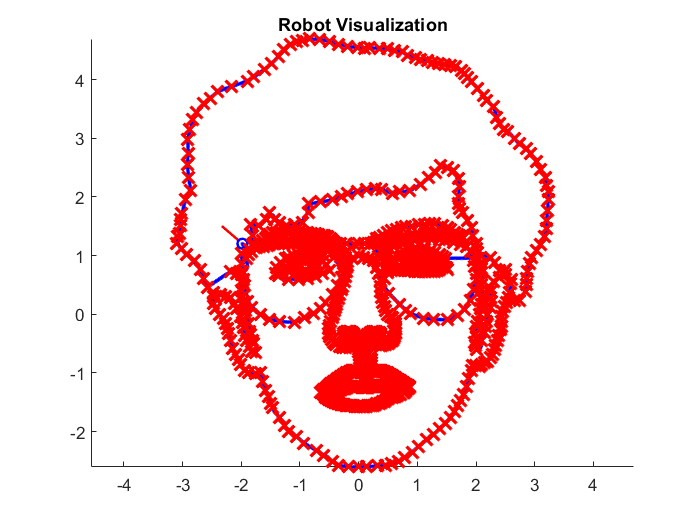


% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 8;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

***Explicación***

Debido a la gran cantidad de puntos utilizados para el trazado de las características faciales (43 veces el abecedario, lo que resulta en un total de 1118 puntos), es crucial mantener la fidelidad en los detalles del rostro. Para lograr esto utilizando el software GeoGebra, se emplean puntos para caracterizar la cara. Considerando que no se requieren curvas complejas, sino más bien puntos consecutivos para definir las formas, opté por utilizar nuevamente el algoritmo de waypoints. Este enfoque ha demostrado ser robusto para seguir puntos de manera eficiente y precisa, minimizando el tiempo y manteniendo el control del trazo. Así, el uso del algoritmo de waypoints resulta conveniente y útil para este propósito. 

No obstante, considero que se puede reducir la cantidad de puntos a la mitad de los empleados sin perder mucha calidad en los detalles del rostro, agilizando así el procesamiento y recorrido del bot pot todos los puntos indicados.